`我们前面所介绍在MATLAB所做的运算，是适合于所要计算的算式不太长或是想以交谈式方式做运算，如果要计算的算式很长有数十行或是须要一再执行的算式，则那样的方式就行不通了。。`

`MATLAB提供了所谓的 M-file 的方式，可让使用者自行将指令及算式写成巨集程式然后储存成一个特别的文档，其扩展名是m，譬如 picture.m，其中的picture就是文件名称。`

`函数与`MATLAB`工作空间之间的通信，只通过传递给它的变量和通过它所创建的输出变量。在函数内中间变量不出现在`MATLAB`工作空间，或与`MATLAB`工作空间不交互。一个函数的`M`文件的第一行把`M`文件定义为一个函数，并指定它的名字。它与文件名相同，但没有`**.m** `扩展名。它也定义了它的输入和输出变量。`

**M**`文件函数之间可以互相调用`**.**

M`文件函数``必须遵循以下特定的``规则``。`

   `1.`  `函数名和文件名必须相同。例如，函数``fliplr` `存储在名为``fliplr.m` `文件中。`

    `2.`  `MATLAB``头一次执行一个``M``文件函数时，它打开相应的文本文件并将命令编辑成存储器的内部表示，以加速执行以后所有的调用。``如果函数包含了对其它``M``文件函数的引用，它们也同样被编译到存储器。普通的脚本``M``文件不被编译，即使它们是从函数``M``文件内调用；打开脚本``M``文件，调用一次就逐行进行注释。`

    `3.`  `在函数``M``文件中，到第一个非注释行为止的注释行是帮助文本。当需要帮助时，返回该文本。例如， ``» help fliplr``返回上述前八行注释。`

    `4.` `第一行帮助行，名为``H1 ``行，是由``lookfor` `命令搜索的行。`

    `5.`  `函数可以有零个或更多个输入参量。函数可以有零个或更多个输出参量。`

    `6.`  `函数可以按少于函数``M``文件中所规定的输入和输出变量进行调用，但不能用多于函数``M``文件中所规定的输入和输出变量数目。如果输入和输出变量数目多于函数``M``文件中``function` `语句一开始所规定的数目，则调用时自动返回一个错误。`

    `7.`  `当函数有一个以上输出变量时，输出变量包含在括号内。例如，``[V,D] = eig(A)``。不要把这个句法与等号右边的``[V,D] ``相混淆。右边的``[V,D] ``是由数组``V``和``D ``所组成。`

    `8.`  `当调用一个函数时，所用的输入和输出的参量的数目，在函数内是规定好的。函数工作空间变量``nargin` `包含输入参量个数；函数工作空间变量``nargout`` 包含输出参量个数。事实上，这些变量常用来设置缺省输入变量，并决定用户所希望的输出变量。`

% area picture%输入试试看E:\my_Gitbook\Matlab
% cmd直接输入matlab -nosplash -nodesktop -r picture%E:\my_Gitbook\Matlab（m文件注意不加.m）


`例:` ,`计算`f(1)f(2)+f2(3)

% 选对目录
fun1(1)*fun1(2)+fun1(3)*fun1(3)

ans = -12.6023

fact(3)%阶乘函数

ans = 6

s = 28.2743

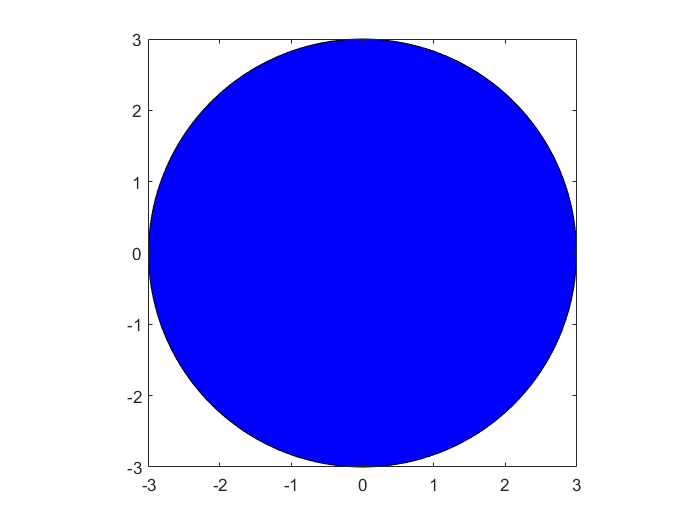

s=circle(3)

sa=circle(3,'r-')

sa = 28.2743

**MATLAB**`控制流`

`For循环 `

For`循环允许一组命令以固定的和预定的次数重复。`For`循环的一般形式是：`

              for  x = array

                  {commands}

              end

`可按需要嵌套 可以利用break命令跳出for循环`

%用for循环指令来寻求Fibonacc数组中第一个大于10000的元素。
n=100;a=ones(1,n);
for i=3:n
     a(i)=a(i-1)+a(i-2);
     if a(i)>=10000
        a(i),
        break;  %跳出所在的一级循环。
     end;
end,

ans = 10946

i  

i = 21

**While **`循环`

`与`For`循环以固定次数求一组命令的值相反，`While `循环以不定的次数求一组语句的值。`

While`循环的一般形式是：`

                      whileexpression

                          {commands}

                      end

 `只要在表达式里的所有元素为真，就执行`**while**`和`**end **`语句之间的`**{commands}**`。`

`可以利用``break``命令跳出``while``循环`

`while``循环可按需要嵌套。`

x = zeros(1,6); % x是一个的零矩阵 
i = 1; 
while i <= 6, 
x(i) = 1/i; 
i = i+1; 
end 
x

x =     1.0000    0.5000    0.3333    0.2500    0.2000    0.1667


Fibonacci数组中第一个大于10000的元素。

a(1)=1;a(2)=1;i=2;
while  a(i)<=10000
	  a(i+1)=a(i-1)+a(i); 	%当现有的元素仍小于10000时，求解下一个元素。
	  i=i+1;
end;
i,a(i),  

i = 21

ans = 10946

**if-else-end**`分支结构`

`很多情况下，命令的序列必须根据关系的检验有条件地执行。在编程语言里，这种逻辑由某种`If-Else-End`结构来提供。最简单的`If-Else-End`结构是：`

                    if  expression

                         {commands}

                    end

     `如果在表达式中的所有元素为真`**(**`非零`**)**`，那么就执行`**if**`和`**end**`语言之间的`**{commands}**

`假如有两个选择，`**If-Else-End**`结构是：`

            if  expression 

                commands evaluated if True 

            else

                commands evaluated if False

            end

`在这里，如果表达式为真，则执行第一组命令；如果表达式是假，则执行第二组命令。`

    `当有三个或更多的选择时，`If-Else-End`结构采用形式`

         if expression1

            commands evaluated if expression1 is True 

         elseif expression2

            commands evaluated if expression2 is True 

         elseifexpression3

            commands evaluated if expression3 is True 

         elseifexpression4

            commands evaluated if expression4 is True 

         elseif`……`

            `．`

            `．`

            `．`

         else

            commands evaluated if no other expression  is True 

         end

    `最后的这种形式，只和所碰到的、与第一个真值表达式相关的命令被执行；接下来的关系表达式不检验，跳过其余的`**If-Else-End**`结构。而且，最后的`**else**`命令可有可无。`

if rand(1)>0.5
disp('i love you')
else
disp('i donot love you')
end

i love you


**switch-case**`结构`

% 学生的成绩管理，用来演示switch结构的应用。
%划分区域：满分(100)，优秀(90-99)，良好(80-89)，及格(60-79)，不及格(<60)。
clc;
clear;
close all;
for i=1:10
    a{i}=89+i;
    b{i}=79+i;
    c{i}=69+i;
    d{i}=59+i;
end
N = input('输入分数');
switch N
   case 100 					%得分为100时
      S ='满分';		%列为'满分'等级
   case a     					%得分在90和99之间
      S =' 优秀';  	%列为'优秀'等级
   case b    					%得分在80和89之间
      S =' 良好';  	%列为'良好'等级
   case c     				%得分在60和79之间
      S =' 及格';    %列为'及格'等级
   case d
     S =' 及格'; 
         
   otherwise  				%得分低于60。
      S ='不及格';   %列为'不及格'等级 
   end
   disp(S)

不及格


**try-catch**`结构`

`【例】`try-catch`结构应用实例。`

clear,N=4;A=magic(3)   %设置3行3列矩阵A。
try
   A_N=A(N,:),      %取A的第N行元素

A =      8     1     6
     3     5     7
     4     9     2


catch
     A_end=A(end,:),    %如果取A(N,:)出错，则改取A的最后一行。
end
lasterr         %显示出错原因  


A_end =      4     9     2


ans = 'Index exceeds matrix dimensions.'

   361



    11    22    33
    44    55    66
    77    88    99



this is a string


The area is 31415.92654


The area is 314159.26536


this is an error